# Check fastICA on random signals 

create matrix with 50 cells and 100 time points, with 3 source signals 

%% random combination of signals of 3 sources
N=100; %data size
v=[0:N-1];
sig=[];
sig(1,:)=sin(v/2); %sinusoid
sig(2,:)=((rem(v,23)-11)/9).^5; %funny curve
sig(3,:)=((rem(v,27)-13)/9); %saw-tooth
sig(4,:)=((rand(1,N)<.5)*2-1).*log(rand(1,N)); %impulsive noise
coef=[10*rand(1,8),rand(1,42);
rand(1,15),10*rand(1,5),rand(1,30);
rand(1,25),10*rand(1,5),rand(1,20);
rand(1,44),10*rand(1,6)];
% signal=sig'*coef;
signal=sig'*coef+0.0001*(rand(100,50)-0.5); % -> see if some noise are added the results
% will be different 

## run fastica

[ic, A, W] = fastica(signal','numOfIC',6);

Number of signals: 50
Number of samples: 100
Calculating covariance...
Dimension reduced to 4 due to the singularity of covariance matrix
Selected [ 4 ] dimensions.
Smallest remaining (non-zero) eigenvalue [ 66.1478 ]
Largest remaining (non-zero) eigenvalue [ 313.82 ]
Sum of removed eigenvalues [ 3.61536e-08 ]
[ 100 ] % of (non-zero) eigenvalues retained.
Whitening...
Check: covariance differs from identity by [ 6.92779e-16 ].
Used approach [ defl ].
Used nonlinearity [ pow3 ].
Starting ICA calculation...
IC 1 ...............computed ( 15 steps ) 
IC 2 .............computed ( 13 steps ) 
IC 3 ......computed ( 6 steps ) 
IC 4 ..computed ( 2 steps ) 
Done.
Adding the mean back to the data.


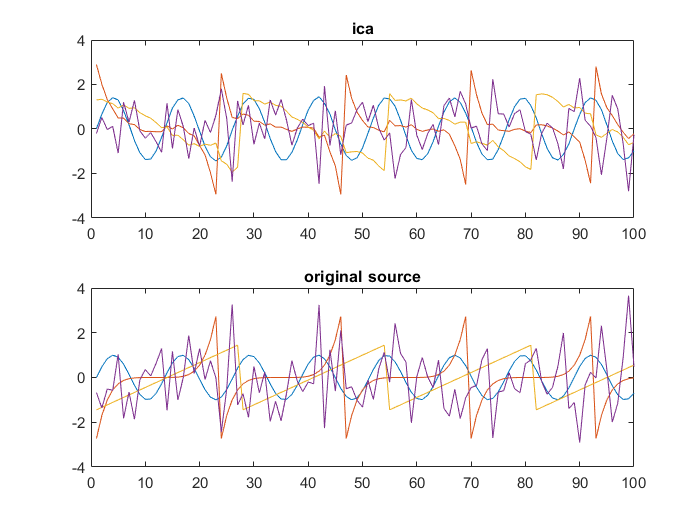

% ic=W*input; W = components x weights on cell
%% plot sources and ics
figure
subplot(2,1,1)
plot(ic')
title('ica')
subplot(2,1,2)
plot(sig')
title('original source')

corr(ic',sig')

ans =     0.9998    0.1201   -0.0607    0.0203
   -0.0035   -0.9791   -0.1420   -0.1664
    0.0002    0.1452   -0.9821   -0.1898
    0.0179    0.0770    0.1080   -0.9674


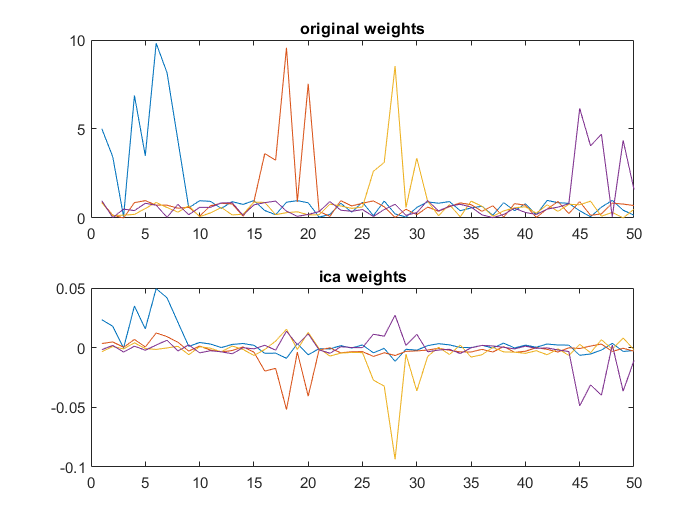

%% check weights on cells
figure
subplot(2,1,1)
plot(coef')
title('original weights')
subplot(2,1,2)
plot(W')
title('ica weights')

corr(coef',W')

ans =     0.9701    0.3733    0.1364    0.1303
   -0.2000   -0.9300    0.3083    0.2320
   -0.2041   -0.0265   -0.9734    0.4186
   -0.2061    0.1207    0.1378   -0.9002
